close all
clear
clc

path = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Lab5\shapesCorner.tif"

path = "C:\Users\atche\OneDrive\Documents\MATLAB\EE146\Lab5\shapesCorner.tif"

Img = imread(path);

Img_gray = im2gray(Img);
map_one = edge(Img_gray, 'canny', 0.10); 
map_two = edge(Img_gray, 'canny', 0.50);
map_three = edge(Img_gray, 'canny', 0.6); 

Img_arr = {map_one, map_two, map_three}

Img_arr = 1×3 cell array
    {256×256 logical}    {256×256 logical}    {256×256 logical}


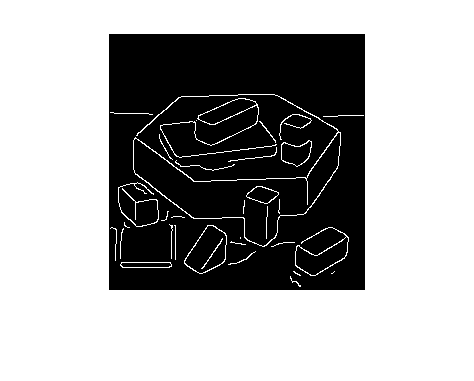


imshow(map_one);

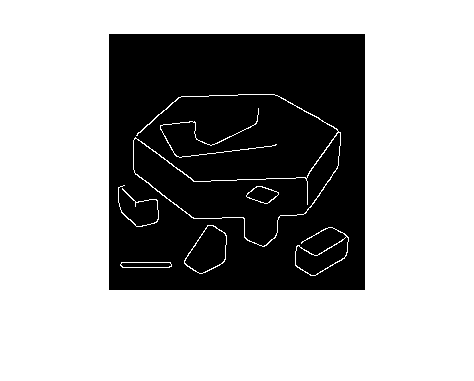

imshow(map_two);

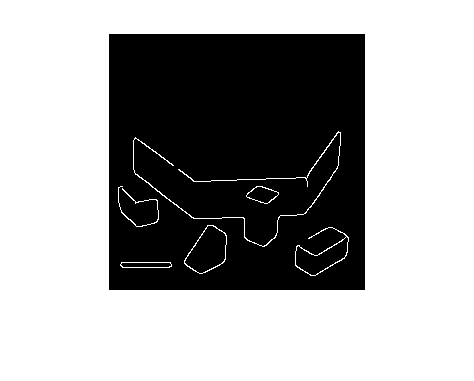

imshow(map_three);

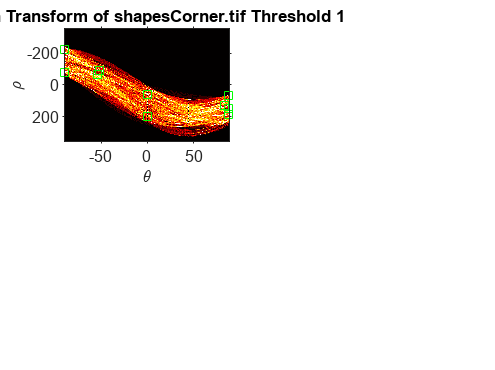

hlines = 1×10 struct array with fields:
    point1
    point2
    theta
    rho


xy =     85   148    13   229    62   125     6    80    63   168    28   105    26   139    81    63   199    79    85   185
   199   144    76   229   174   111    53    80    63   233    87   148    85   185   152    61   199   177   125   184


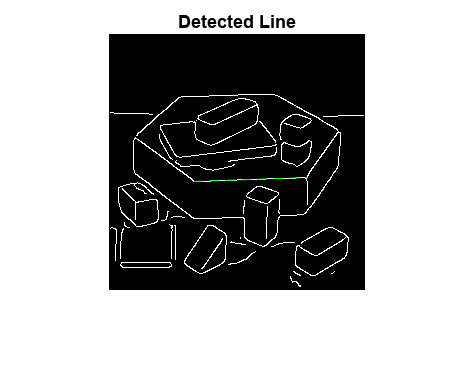

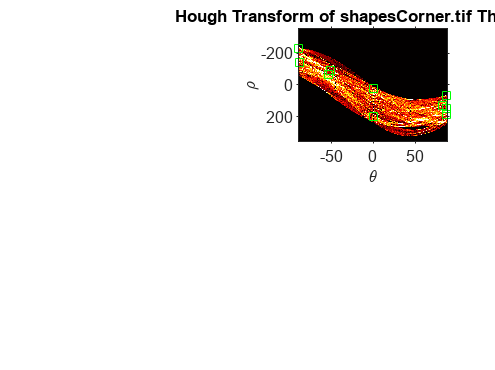

hlines = 1×7 struct array with fields:
    point1
    point2
    theta
    rho


xy =     14   234    85   148    71   124    81    63    28   105    26   139    85   185
    82   234   199   144   167   112   152    61    87   148    85   185   125   184


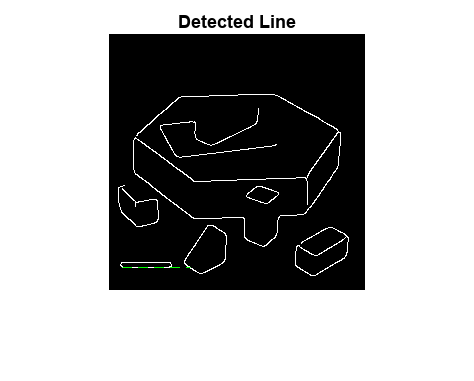

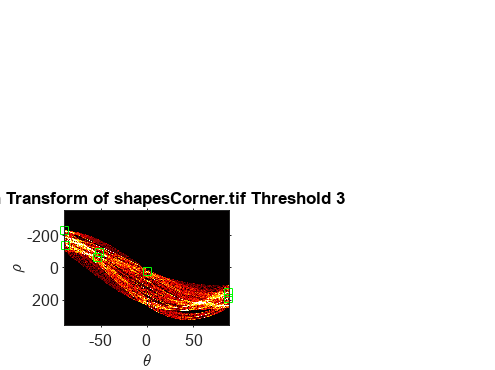

hlines = 1×5 struct array with fields:
    point1
    point2
    theta
    rho


xy =     14   234    85   148    26   139    28   105    85   185
    82   234   199   144    85   185    87   148   125   184


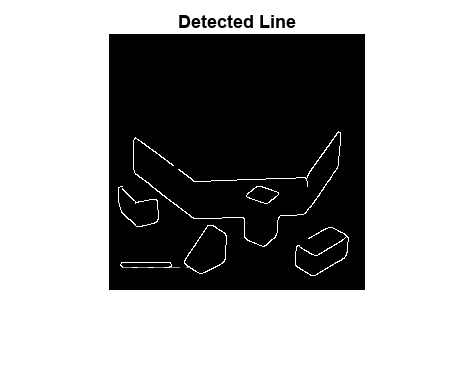


max_dist = zeros(1,3);
min_dist = zeros(1,3);
for i = 1:3
    figure;
    subplot(2,2,i);
    [H, T, R] = hough((Img_arr{i}), 'RhoResolution', 0.5, 'theta', -90:1:89);
    
    imshow(imadjust(rescale(H)), 'XData', T, 'YData', R, 'InitialMagnification','fit');
    title(append('Hough Transform of shapesCorner.tif',' Threshold ', string(i)));
    xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on;
    colormap(gca,hot);
    hPeaks = houghpeaks(H, 10);  
        
    x = T(hPeaks(:,2));
    y = R(hPeaks(:,1));
    plot(x,y, 'gs');

    
    hlines = houghlines(Img_arr{i}, T, R, hPeaks)
    
    xy = [hlines.point1; hlines.point2]        
    figure
    imshow(Img_arr{i});
    hold on
    plot(xy(:,1), xy(:,2), 'g--');
    title('Detected Line');
    dist = zeros(1,(size(xy, 2)/2));
    cnt = 1;
    for j = 1:2:(size(xy, 2)-1)
            
            dist(1,cnt) = sqrt(((xy(1,j) - xy(2,j))^2) - ((xy(1,j+1) - xy(2,j+1))^2));
            cnt = cnt + 1;
    
    end
    max_dist(i) = max(dist);
    min_dist(i) = min(dist);
end